Función que obtiene el Jacobiano de posición y orientación del cuadrúpedo, ya sea de sus patas traseras (2 DOF) o de sus patas delanteras (3 DOF). Para las patas traseras se utiliza geometría, mientras que para las delanteras se emplean los resultados obtenidos a partir de la matriz de Denavit-Hartenberg. 

Uso: `J = cuadJ(q, DOF, IT_B, ET_F)`

- *q* = Configuración del robot

- *DOF* = Número de grados de libertad. Opciones = 2 o 3

- *IT_B* = Transformación de base

- *ET_F* = Transformación de efector final

- *Posicion *= Vector con la posición del efector final

- *Orientacion* = Matriz cuadrada de orientación del efector final

Cálculo del Jacobiano por Métodos Numéricos

Pasos para el cálculo de la cinemática diferencial o Jacobiano por medio de métodos numéricos

- Calcular la cinemática directa $\mathcal{K}(q)$ para una configuración específica $q$.

- Extraer la matriz de rotación $R(q)$ de la matriz de cinemática directa $\mathcal{K}(q)$

- Tomar el elemento $j$ de la configuración $q$. Crear un vector $\delta q$ de ceros con la misma dimensionalidad de $q$. Incrementar únicamente la fila $j$ en una pequeña cantidad (0.01 por ejemplo).

 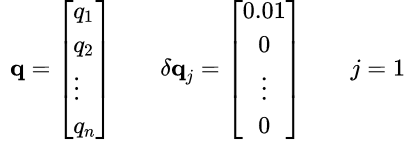                

- Obtener el cambio en la cinemática directa empleando $\mathcal{K}(q)$ y la definición de la derivada. Recordar que $\mathbf{\delta q}$ hace referencia al vector creado en el paso anterior. $\delta q$ consiste del pequeño incremento.

- Se obtendrá una matriz de 4x4. Extraer de esta el cambio en la orientación $\partial R(q)$ y en la posición $\partial o(q)$

- Calcular la matriz anti-simétrica $\mathcal{S}(\omega_{q_j})$ si se sabe que $\partial \mathbf{R(q)} = \dot{\mathbf{R}}(\mathbf q)$ 

- Extraer los componentes de la velocidad angular $\omega_{q_j}$ si se sabe que la matriz anti-simétrica tiene esta forma

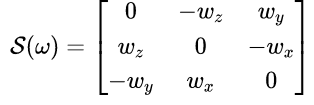

- Con los componentes de la velocidad angular crear un vector columna

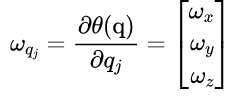

- Crear la columna $j$ del jacobiano concatenando $\partial \mathbf{o}(q)$ y $\partial \mathbf{\theta}(q)$. Al vector columna con ambas cantidades se le denomina "Velocidad espacial".

- Repetir esto para cada fila $j$ de la configuración $q$.

function J = cuadJ(q, DOF, varargin)

    % Jacobiano analítico para pata de 2 DOF. No se pudo implementar
    % case 2  
    %  A = 80/1000;
    %  B = 129/1000;
    %  J = [-A*sin(q(1))  B*sin(q(2)); 
    %        A*cos(q(1))  B*cos(q(2));
    %                  1            1];
    
    % Transformaciones de base y de herramienta
    IT_B = varargin{1};
    ET_F = varargin{2};
    
    % Dimensión de la configuración
    DimConfig = size(q,1);
    
    % Se calcula la cinemática directa de la pata
    T = cuadFK(q, DOF, IT_B, ET_F);
    R = T(1:3, 1:3);
    
    % Se inicializa el Jacobiano
    J = zeros(6, DimConfig);
    
    % Cálculo de la j-ésima columna del jacobiano
    for j = 1:size(q)
        dq = zeros(DimConfig, 1);
        dq(j) = 0.001;
        
        dT = cuadFK(q + dq, DOF, IT_B, ET_F);            
        dK = (dT - T) / dq(j);
        
        dO = dK(1:3, 4);
        dR = dK(1:3, 1:3);
        Sw = dR * R';
        
        dWx = Sw(3,2);
        dWy = Sw(1,3);
        dWz = Sw(2,1);
        
        J(:, j) = [dO ; dWx; dWy; dWz];
    end

end